# Assignment 1

## Data Processing

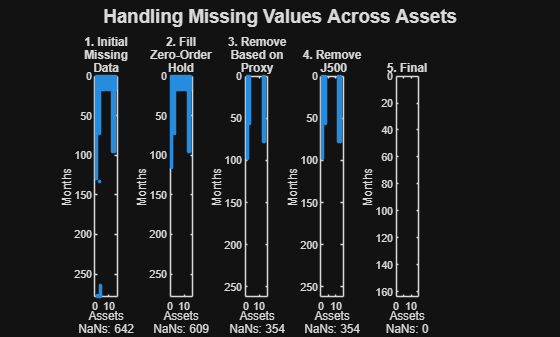


% 0. Clear environment and remove all plots
clc % clears the command window
close all %removes all figures
clear % clears the workspace

% 1. Load the data
% 1.1 Loading the excel file into matlab
fileName =  "C:\Users\User\OneDrive - University of Cape Town\Notes Honours 2025\Portfolio Theory\Portfolio_Theory_A1\Data\PT-DATA-ALBI-JIBAR-JSEIND-Daily-1994-2017.xlsx";
excelSheetNames = sheetnames(fileName);
% 1.2 Preallocate cell array before looping
data{numel(excelSheetNames)} = [];
% 1.3 Load the dataset by sheet
for sheet = 1:numel(excelSheetNames)
    data{sheet} = readtimetable(fileName, 'Sheet', excelSheetNames{sheet}, 'VariableNamingRule', 'preserve');
end

% 2. Filter and Clean Data: Keep Only Relevant Tickers and Columns
% 2.1 Define a list of all the assets we want to include in the universe
%      - Includes RATESTEFI, ALBI, key J-bonds, variable J5x tickers, and major JSE indices
variableTickers = string("J5" + (10 : 10 : 90));
entities = {'RATESTEFI', 'RATEJ2Y4', 'ALBI', 'J203', 'J500', 'J330', 'J331', variableTickers{:}};
% 2.2 Loop over each sheet in the dataset
for i = 1:numel(data)
    % 2.2.1 Keep only TRI (Total Return Index) columns for sheets 3 and 4
    if i == 3
        allVarTable = data{i}; 
        TRITable = allVarTable(:, (3:3:27));   % select every 3rd column (TRI)
        TRITable = TRITable(4:end,:);          % remove the first 3 rows (NaNs)
        % Convert all columns to numeric if they are cells/strings 
        % (i.e. J500 needs converting)
        for col = 1:width(TRITable)
            colName = TRITable.Properties.VariableNames{col};
            % Check if the column is cell or string
            if iscell(TRITable.(colName)) || isstring(TRITable.(colName))
                TRITable.(colName) = str2double(TRITable.(colName));  % convert to numeric
            end
        end
        data{i} = TRITable;
    elseif i == 4
        allVarTable = data{i};
        allVarTable = removevars(allVarTable, ["SOURCE68779","Var2"]); % remove unwanted columns
        TRITable = allVarTable(:, (4:4:19));   % select every 4th column (TRI)
        TRITable = TRITable(4:end,:);           % remove the first 3 rows (NaNs)
        data{i} = TRITable;
    else
        % 2.2.2 For other sheets, just skip the first 3 rows
        data{i} = data{i}(4:end, :);  
    end
    % 2.3 Match column names to entities (whitelist)
    opts = data{i}.Properties;                  % get table properties
    variableMatch = zeros(size(opts.VariableNames));  % preallocate array for matching
    % 2.3.1 Perform string comparison for column matching
    if i == 2 
        % Sheet 2: compare first 8 characters to avoid unwanted matches
        for k = 1:numel(entities)
            variableMatch(strncmp(opts.VariableNames, entities{k}, 8)) = k;
        end
    else
        % Other sheets: compare first 4 characters
        for k = 1:numel(entities)
            variableMatch(strncmp(opts.VariableNames, entities{k}, 4)) = k;
        end
    end
    % 2.3.2 Identify and remove columns not in the whitelist
    idx = find(variableMatch == 0);                    % find unwanted tickers
    tickersToBeRemoved = opts.VariableNames(idx);      % get their names
    data{i} = removevars(data{i}, tickersToBeRemoved); % remove them from the table
    % 2.4 Clean up remaining column names
    %      - Remove any text after ':' to simplify variable names
    hasColon = contains(data{i}.Properties.VariableNames, ':');     
    data{i}.Properties.VariableNames(hasColon) = extractBefore(data{i}.Properties.VariableNames(hasColon), ':');
end

% 3. Clean and convert into a single timetable
allDataTable = synchronize(data{1},data{2},data{3},data{4});
%Rename variables
allDataTable = renamevars(allDataTable,{'RATESTEFI','RATEJ2Y4','J203'}, {'STEFI','JIBAR','ALSI'});

% 4. Down-sample (by decimation)
% 4.1 Decimate the daily data to monthly data
allDataTable = convert2monthly(allDataTable); % Home -> Add-ons -> Financial Toolbox

% 5. Visualising and Handling Missing Data
% Helper function to get number of NaNs
countNaNs = @(T) sum(isnan(table2array(T)),'all');
% 5.1 Initial Missing Data Visualisation
figure;
subplot(1,6,1);
spy(isnan(table2array(allDataTable)));
xlabel(["Assets","NaNs: " + countNaNs(allDataTable)]);
ylabel("Months")
title({"1. Initial","Missing","Data"})
% 5.2  Fill Missing Data with Zero-Order Hold (Last Observation Carried Forward)
allDataTable = fillmissing(allDataTable,'previous');
subplot(1,6,2);
spy(isnan(table2array(allDataTable)));
xlabel(["Assets","NaNs: " + countNaNs(allDataTable)]);
ylabel("Months")
title({"2. Fill","Zero-Order","Hold"})
% 5.3 Remove Rows Using the Asset With The Least NaN's (best proxy asset)
[minNans,idx] = min(sum(isnan(allDataTable{:,:}),1));
rmmissingProxy = allDataTable.Properties.VariableNames{idx}; % Find the column with the FEWEST missing values
allDataTable = rmmissing(allDataTable,"DataVariables",rmmissingProxy); % Remove rows where the proxy has NaNs
subplot(1,6,3);
spy(isnan(table2array(allDataTable)));
xlabel(["Assets","NaNs: " + countNaNs(allDataTable)]);
ylabel("Months")
title({"3. Remove","Based on","Proxy"})
% 5.4 Drop a Specific Variable (J500 - discontinued)
idxJ500=contains(allDataTable.Properties.VariableNames,'J500');
idx = 1:width(allDataTable);
allDataTable = allDataTable(:,idx(~idxJ500));
subplot(1,6,4);
spy(isnan(table2array(allDataTable)));
xlabel(["Assets","NaNs: " + countNaNs(allDataTable)]);
ylabel("Months")
title({"4. Remove"," J500"})
% 5.5 Remove Leading Rows with Missing Data
% Detect rows at the start of the dataset that contain NaNs and trim them
idx = isnan(allDataTable{:,:});
allDataTable = allDataTable(max(find(idx,max(max(cumsum(idx)))))+1:end,:);
subplot(1,6,5);
spy(isnan(table2array(allDataTable)));
xlabel(["Assets","NaNs: " + countNaNs(allDataTable)]);
ylabel("Months")
title("5. Final")
sgtitle('Handling Missing Values Across Assets', 'FontSize', 14, 'FontWeight', 'bold');

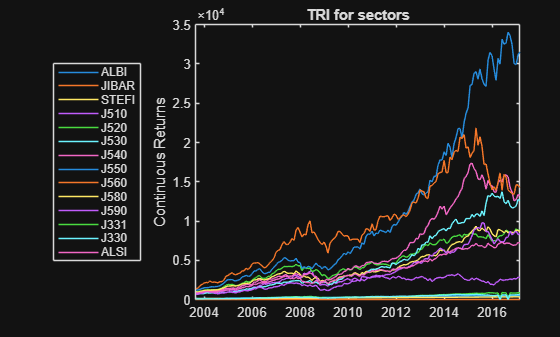


% 6. Visualise the data and the returns on a single plot
% 6.1 Compute simple returns (Rt = (Pt - Pt-1)/Pt-1)
allDataReturnsTable = tick2ret(allDataTable,'Method','continuous');
% 6.2 Plot of the time series
figure;
plot(allDataTable.Time,allDataTable{:,:})
ylabel("Continuous Returns")
title("TRI for sectors")
legend(allDataTable.Properties.VariableNames,Location="westoutside")

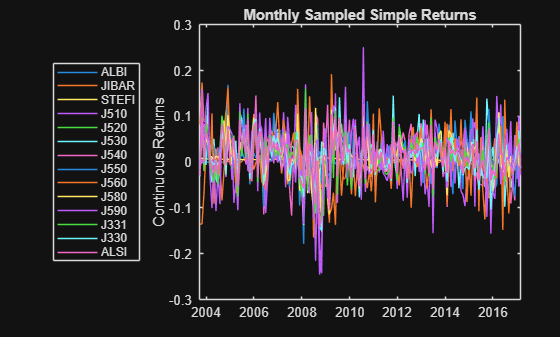

% 6.3 Plot of returns
figure;
plot(allDataReturnsTable.Time,allDataReturnsTable{:,:})
ylabel("Continuous Returns")
title("Monthly Sampled Simple Returns")
legend(allDataTable.Properties.VariableNames,Location="westoutside")


% 7. Manage Missing Data
% 7.1 Check if there is still missing data or cells of zero
any(isnan(allDataReturnsTable{:,:}))

ans = 1×14 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0


nZeros = sum(allDataTable{:,:} == 0,'all');
disp(['Total zero values: ', num2str(nZeros)]);

Total zero values: 4


% 7.2 Compute the Arithmetic means correcting for missing data (NAN)
portfolioMean = mean(allDataReturnsTable{:,:},'omitnan');
portfolioStdDev = std(allDataReturnsTable{:,:},1,'omitnan');
portfolioVariance = var(allDataReturnsTable{:,:},'omitnan');
% 7.3 Fill those missing values with the previous results
allDataTable{:,:}(allDataTable{:,:} == 0) = NaN; % Replace zeros with NaN
allDataTable = fillmissing(allDataTable,'previous'); % Replace NaNs with the previous observation


### Jibar 3 Month Yield (Close)

% 8. Discounting the 3 month jibar yield
threeMonthJibar = allDataTable{:, 'JIBAR'};

% Convert 3-month JIBAR to monthly equivalent
monthlyJibar = (1 + threeMonthJibar).^(1/3) - 1;

% Update the table with the monthly JIBAR values
allDataTable{:, 'JIBAR'} = monthlyJibar;
mean(monthlyJibar)

ans = 1.0150

## Experiment 1

### Data Set Up

% 1. Split into two sets of data
% 1.1 Number of observations
nObs = size(allDataTable,1);
% 1.2 Choose a split point (e.g. 70% training, 30% test)
splitPoint = floor(0.7 * nObs);
% 1.3 Also keep the dates if you need them
train = allDataTable(1:splitPoint,:);
test  = allDataTable(splitPoint+1:end,:);
disp(['Training rows: ', num2str(size(train,1))]);

Training rows: 114


disp(['Test rows: ', num2str(size(test,1))]);

Test rows: 49


### Training

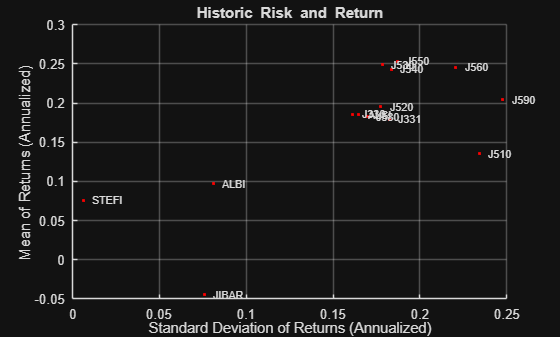

% 2.1 Portfolio Set Up
q = Portfolio('AssetList',train.Properties.VariableNames);
% 2.2 Simple Arithmetic Returns
trainReturnsTable = tick2ret(train,'Method','continuous'); % Change this if needed
q = estimateAssetMoments(q,trainReturnsTable{:,:});
% 2.3 Visualise the Risk-Return Relationship
clf;
portfolioexamples_plot('Historic Risk and Return', ...
	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### Fully invested portfolio with varying risk aversion (efficientFrontier1)

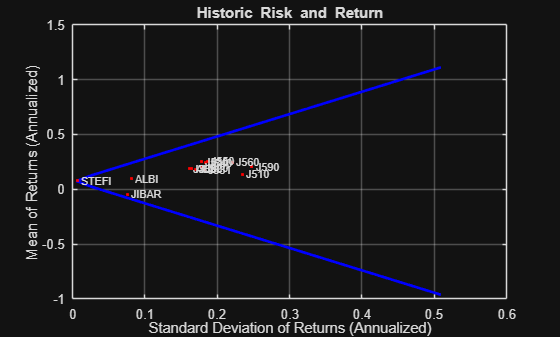

% 3. Fully invested portfolio with varying risk aversion 
function [PortWts, ret, rsk] = efficientFrontier1(q, lambda)
    % 3.1 Fully Invested
    q.AEquality = ones(1,length(q.AssetMean));
    q.bEquality = 1;
    PortWts = NaN(length(lambda),length(q.AssetMean));
    
    % 3.2 Find the optimal portfolio weights
    options = optimoptions('quadprog','Display','off');
    for i = 1:length(lambda)
        f = - lambda(i) * q.AssetMean; % This moves the solution up along the efficient frontier
        H = q.AssetCovar; %the covariance matrix
        PortWts(i,:) = quadprog(H, f, [], [], q.AEquality, q.bEquality, [], [], [], options) ;
    end
    % 3.3 Compute Portfolio Risk and Return
    ret = estimatePortReturn(q, PortWts');
    rsk = estimatePortRisk(q,PortWts');
    %ret = PortWts * q.AssetMean';
    %rsk = sqrt(diag(PortWts * q.AssetCovar * PortWts'));
end

% 3.4 Efficient Frontier
% Create the range of risk aversion parameters
lambda = linspace(-0.25,0.25,45);
[Wts,ret1,rsk1] = efficientFrontier1(q,lambda);
% 3.5 Plot the Curve
clf;
portfolioexamples_plot('Historic Risk and Return', ...
	{'line', rsk1, ret1}, ...
	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### $\Rightarrow$Excluding Cash and Market Indices (efficientFrontier2)

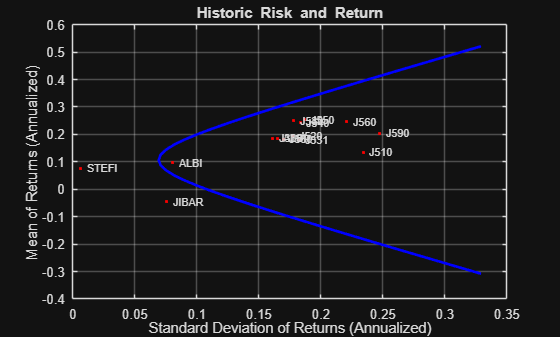

% 4. Exclude the Cash and Market Indices
function [PortWts, ret, rsk] = efficientFrontier2(trainReturnsTable, lambda, includingTickers)
    % 4.1 Statistics
    Returns = trainReturnsTable{:,includingTickers};
    mu = mean(Returns); % Use Mean With Excluded Indices
    Sigma = cov(Returns); % Use Covar With Excluded Indices
    
    % 4.2 Fully Invested
    Aeq = ones(1,length(mu));
    beq = 1;
    % initialise the weights
    PortWts = NaN(length(lambda),length(mu));
    
    % 4.3 Find the optimal portfolio weights
    optionsQP = optimset('quadprog')';
    optionsQP= optimset(optionsQP,'Display','off');
    for i = 1:length(lambda)
        f = - lambda(i) * mu; % This moves the solution up along the efficient frontier
        H = Sigma; %the covariance matrix
        [PortWts(i,:),fVal,exitFlag(i)] = quadprog(H,f,[],[],Aeq,beq,[],[],[],optionsQP);
    end
    
    % 4.4 compute risk and return 
    ret = PortWts * mu';
    rsk = sqrt(diag(PortWts * Sigma * PortWts'));
end

% 4.5 Efficient frontier
% Tickers we are excluding 
tickers = setdiff(train.Properties.VariableNames,{'STEFI','JIBAR','ALSI','J330','J331'});
lambda = linspace(-0.25,0.25,45);
[Wts, ret2,rsk2] = efficientFrontier2(trainReturnsTable,lambda,tickers );

%  4.6 Plot
clf;
portfolioexamples_plot('Historic Risk and Return', ...
	{'line', rsk2, ret2}, ...
    {'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

%	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### $\Rightarrow \;$No short selling constraint (Method 1: Adjusting Risk Aversion) (efficientFrontier3)

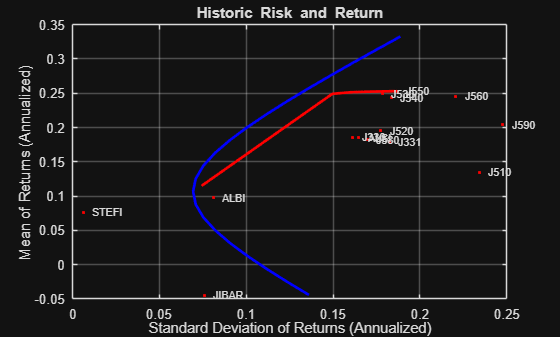

% 5. Exclude the Cash and Market Indices
function [PortWts,ret, rsk] = efficientFrontier3(trainReturnsTable, lambda, includingTickers)
    % 5.1 Statistics
    Returns = trainReturnsTable{:,includingTickers};
    mu = mean(Returns); % Use Mean With Excluded Indices
    Sigma = cov(Returns); % Use Covar With Excluded Indices
    
    % 5.2 Fully Invested (equality constraint)
    Aeq = ones(1,length(mu));
    beq = 1;
    % initialise the weights
    PortWts = NaN(length(lambda),length(mu));
    
    % 5.3 No Short-selling (inequality constraint)
    A = -eye(length(mu));
    b = zeros(length(mu),1);
    
    % 5.4 Find the optimal portfolio weights
    optionsQP = optimset('quadprog')';
    optionsQP= optimset(optionsQP,'Display','off');
    for i = 1:length(lambda)
        f = - lambda(i) * mu; % This moves the solution up along the efficient frontier
        H = Sigma; %the covariance matrix
        [PortWts(i,:),fVal,exitFlag(i)] = quadprog(H,f,A,b,Aeq,beq,[],[],[],optionsQP);
    end
    
    % 5.5 compute risk and return
    ret = PortWts * mu';
    rsk = sqrt(diag(PortWts * Sigma * PortWts'));
end

% 5.6 Efficient Frontier
% Tickers we are excluding 
tickers = setdiff(train.Properties.VariableNames,{'STEFI','JIBAR','ALSI','J330','J331'});
% Create the range of risk aversion parameters
lambda = 12*linspace(0,1,25);
[Wts, ret3, rsk3] = efficientFrontier3(trainReturnsTable, lambda, tickers);

% 5.7 Plot
clf;
portfolioexamples_plot('Historic Risk and Return', ...
    {'line', rsk2(15:end-10), ret2(15:end-10)}, ...
	{'line', rsk3, ret3, '','r'}, ...
    {'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

%	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### $\iff \;$No short selling constraint (Method 2: Adjusting Required Returns) (efficientFrontier4)

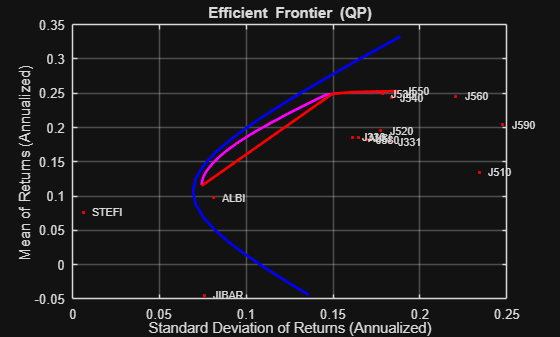

% 6. Exclude the Cash and Market Indices
function [PortWts,ret, rsk] = efficientFrontier4(trainReturnsTable, exceedingValue, includingTickers)
    % 6.1 Statistics
    Returns = trainReturnsTable{:,includingTickers};
    mu = mean(Returns); % Use Mean With Excluded Indices
    Sigma = cov(Returns); % Use Covar With Excluded Indices
    
    % 6.2 Create the range of risk aversion parameters
    retTargetAll = min(mu):((max(mu)-min(mu))/90):max(mu);
    retTarget = retTargetAll(retTargetAll > exceedingValue);
    
    % 6.3 Equality constraint (fully invested)
    Aeq = ones(1,length(mu));
    beq = 1;
    % initialise the weights
    PortWts = NaN(length(retTarget),length(mu));
    
    % 6.4 No Short-selling (upper and lower bounds)
    ub = ones(length(mu),1);
    lb = zeros(length(mu),1);
    
    % 6.5 Equality constraint (return target)
    Aeq = [Aeq; mu];
    beq = [beq; 0];
    
    % 6.6 Find the optimal portfolio weights
    optionsQP = optimset('quadprog')';
    optionsQP= optimset(optionsQP,'Display','off');
    for i = 1:length(retTarget)
        beq(2) = retTarget(i); % This moves the solution up along the efficient frontier
        H = Sigma; %the covariance matrix
        [PortWts(i,:),fVal,exitFlag(i)] = quadprog(H,zeros(size(mu))',[],[],Aeq,beq,lb,ub,[],optionsQP);
    end
    
    % 6.7 compute risk and return
    ret = PortWts * mu';
    rsk = sqrt(diag(PortWts * Sigma * PortWts'));
end

% 6.8 
% Tickers we are excluding 
tickers = setdiff(train.Properties.VariableNames,{'STEFI','JIBAR','ALSI','J330','J331'});
[Wts, ret4, rsk4 ] = efficientFrontier4(trainReturnsTable,ret3(1),tickers);

%  6.9 Plot
clf;
portfolioexamples_plot('Efficient Frontier (QP)', ...
    {'line', rsk2(15:end-10), ret2(15:end-10)}, ...
	{'line', rsk4, ret4,'','m'}, ...
	{'line', rsk3, ret3,'','r'}, ...
    {'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

%	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});


#### $\Rightarrow \;$Maximum Sharpe Ratio Portfolio (maxSharpeRatio)

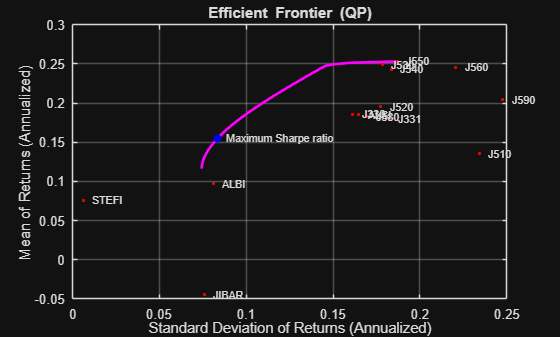

% 7 Exclude the Cash and Market Indices
function [PortWts,ret, rsk, ERFR] = maxSharpeRatio(trainReturnsTable, includingTickers, riskFreeTicker)
    % 7.1 Statistics
    Returns = trainReturnsTable{:,includingTickers};
    mu = mean(Returns); % Use Mean With Excluded Indices
    Sigma = cov(Returns); % Use Covar With Excluded Indices
    
    % 7.2 Risk free rate
    RFR = trainReturnsTable{:,riskFreeTicker};
    % average risk free rate (when to use geometric average)
    ERFR = mean(RFR); 
    
    % 7.3 Equality constraint (fully invested)
    Aeq = ones(1,length(mu));
    beq = 1;
    % initialise the weights for Equally weighted portfolio 
    Wts0 = ones(size(mu))/length(mu);
    
    % 7.4 No Short-selling (upper and lower bounds)
    ub = ones(length(mu),1);
    lb = zeros(length(mu),1);
    
    % 7.5 objective function to maximise the SR
    fn0 = @(x) (-(x*mu' - ERFR)/sqrt(x*Sigma*x'));
    
    % 7.6 Use SQP to solve for the tangency portfolio
    options = optimoptions(@fmincon,'Algorithm','sqp','OptimalityTolerance',1e-8,'Display','off');
    PortWts = fmincon(fn0,Wts0,[],[],Aeq,beq,lb,ub,[],options); % Maximum Sharpe Ratio Portfolio Weights
    
    % 7.7 compute risk and return
    ret = PortWts*mu';
    rsk = sqrt(PortWts*Sigma*PortWts');
end

% 7.8 Tickers we are excluding 
tickers = setdiff(train.Properties.VariableNames,{'STEFI','JIBAR','ALSI','J330','J331'});
[Wts_train,retSR, rskSR,ERFR_Train] = maxSharpeRatio(trainReturnsTable, tickers, 'JIBAR');

% 7.9 Plot
clf; 
portfolioexamples_plot('Efficient Frontier (QP)', ...
	{'line', rsk4, ret4,'','m'}, ...
    {'scatter',rskSR,retSR,{'Maximum Sharpe ratio'},'b'}, ...
    {'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

%	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### Market Security Line

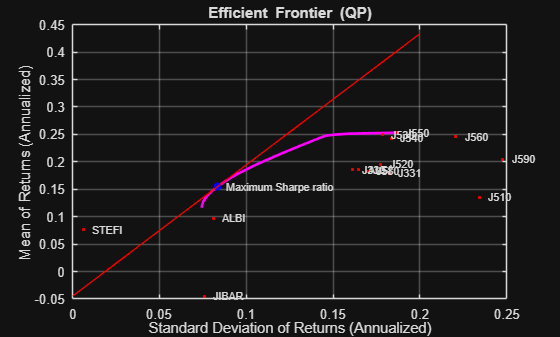

hold on
% 8.1 SML through the tangency portfolio
SML = @(x) (12*ERFR_Train + sqrt(12)*(retSR-ERFR_Train)/rskSR*x);
x = linspace(0,0.20,20);
% 8.2 Plot market line
plot(x,SML(x),'r')
hold off

% legend("Market Line")

#### Visualise the Sharpe Ratio Values

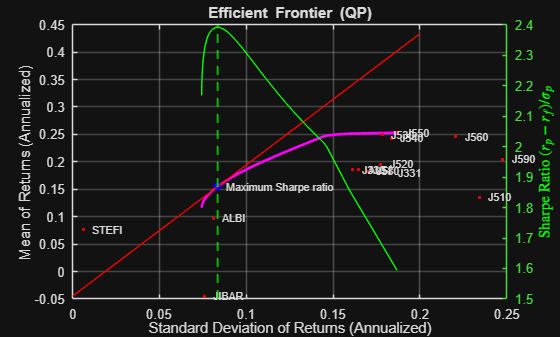

hold on
% 9.1 Plot the Sharpe Ratio against risk levels
yyaxis right
ylabel('Sharpe Ratio ${ ( r_p -r_{f} ) / \sigma_p }$','interpreter','latex','Color','g')
% 9.2 plot the Sharpe Ratio against risk level
plot(sqrt(12)*rsk4,sqrt(12)*(ret4-ERFR_Train)./rsk4,'g')
xline(rskSR*sqrt(12), '--g', 'LineWidth', 1.5, ...
    'Label', '', 'LabelVerticalAlignment','bottom', 'LabelOrientation','horizontal');
hold off

### Testing Buy Hold

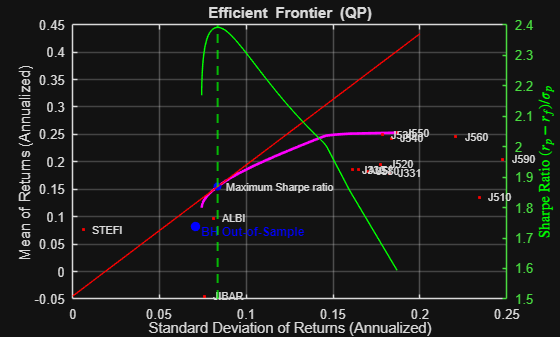

% 10. Buy-and-Hold (BH) Strategy on Test Dataset
% A strategy where the portfolio is invested according to initial weights and held without rebalancing, allowing asset allocations to drift with market movements.

% 10.1 Compute Buy Hold Out of Sample Portfolio statistics
function [ret, rsk] = buyHold(testReturnsTable, Wts, includingTickers)
    % Exclude unwanted tickers
    R = testReturnsTable{:, includingTickers};
    [nPeriods, nAssets] = size(R);
    % Start with a notional portfolio value of 1 and allocate it based on initial weights
    assetValues = Wts; 
    portValues = zeros(nPeriods + 1, 1);
    portValues(1) = sum(assetValues); % Initial portfolio value is the sum of initial asset values
    for t = 1:nPeriods
        % Grow each asset by its return for the current period
        assetValues = assetValues .* (1 + R(t, :));
        % The portfolio value is the sum of the new asset values
        portValues(t+1) = sum(assetValues);
    end
    % Calculate monthly returns from the portfolio value series
    portRetSeries = (portValues(2:end) - portValues(1:end-1)) ./ portValues(1:end-1);
    % Calculate the mean and standard deviation of returns
    ret = mean(portRetSeries);
    rsk = std(portRetSeries);
end

function [Sharpe] = sharpeRatioM2Y(ret, rsk, testReturnsTable, riskFreeTicker)
    % Takes in Monthly ret and rsk and outputs an annualised Year sharpe ratio
    ERFR = mean(testReturnsTable{:,riskFreeTicker});
    Sharpe = sqrt(12)*(ret-ERFR)./rsk;
end

% 10.2 Extract test returns (excluding cash and market indices)
tickers = setdiff(train.Properties.VariableNames,{'STEFI','JIBAR','ALSI','J330','J331'});
testReturnsTable = tick2ret(test,'Method','continuous'); % Change this if needed
[bhMean, bhSd] = buyHold(testReturnsTable,Wts_train, tickers);
[bhSharpe] = sharpeRatioM2Y(bhMean, bhSd,testReturnsTable, "JIBAR");

% 10.3 Plot
yyaxis left 
hold on
scatter(sqrt(12) * bhSd, (1 + bhMean)^(12) - 1, 50, 'b', 'filled'); 
text(sqrt(12) * bhSd+0.003, (1 + bhMean)^(12) - 1-0.01, 'BH Out-of-Sample', ...
     'FontSize', 9, 'Color', 'b', 'FontWeight', 'bold');
hold off

### Testing Constant Mix Portfolio

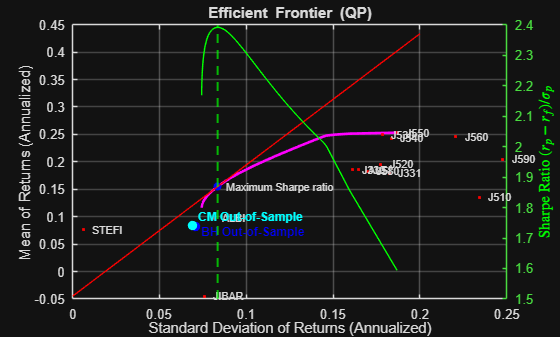

% 11. Constant-Mix (CM) On Test Dataset
% A strategy where the portfolio is periodically rebalanced to maintain fixed target weights, selling assets that have risen and buying those that have fallen to keep risk exposure constant

% 11.1 Compute Constant Mix(CM) Out of Sample Portfolio statistics
function [ret, rsk] = constantMix(testReturnsTable, Wts, includingTickers)
    % Exclude unwanted tickers
    R = testReturnsTable{:, includingTickers};
    [nPeriods, nAssets] = size(R);
    % Start with a notional portfolio value of 1
    portValue = 1;
    monthlyReturns = zeros(nPeriods, 1);
    for t = 1:nPeriods
        % Calculate the portfolio return for the period
        portReturn = Wts * R(t, :)';
        % Update the portfolio value with the new return
        portValue = portValue * (1 + portReturn);
        % Store the monthly portfolio return
        monthlyReturns(t) = portReturn;  
        % Rebalancing happens implicitly by using Wts for the next period's calculation
        % The weights are always constant, so we don't need to explicitly track asset values
    end
    % Calculate the mean and standard deviation of monthly returns
    ret = mean(monthlyReturns);
    rsk = std(monthlyReturns);
end

% 11.2 Extract test returns (excluding cash and market indices)
tickers =setdiff(train.Properties.VariableNames,{'STEFI','JIBAR','ALSI','J330','J331'});
testReturnsTable = tick2ret(test,'Method','continuous'); % Change this if needed
[cmMean,cmSd] = constantMix(testReturnsTable,Wts_train, tickers);
[cmSharpe] = sharpeRatioM2Y(cmMean, cmSd,testReturnsTable, "JIBAR");

% 11.3 Plot
yyaxis left 
hold on
scatter(sqrt(12) * cmSd, (1 + cmMean)^(12 ) - 1, 50, 'c', 'filled'); 
text(sqrt(12) * cmSd+0.003, (1 + cmMean)^(12 ) - 1 + 0.015, 'CM Out-of-Sample', ...
     'FontSize', 9, 'Color', 'c', 'FontWeight', 'bold');
hold off

### Tables for Results Comparison

% 12.1 In-sample statistics
inSharpe = sharpeRatioM2Y(retSR, rskSR, trainReturnsTable, "JIBAR");

% 12.2 Monthly Comparison table
ResultsComparison = table( ...
    [12*retSR; (1 + bhMean)^(12) - 1; (1 + cmMean)^(12) - 1], ...
    [(sqrt(12)*rskSR)^2;  (sqrt(12)*bhSd)^2; (sqrt(12)*cmSd)^2], ...
    [inSharpe; bhSharpe; cmSharpe], ...
    'VariableNames', {'Annualized Mean','Annualized Variance','Annualized Sharpe Ratio'}, ...
    'RowNames', {'In-Sample SR','Out-of-Sample BH', 'Out-of-Sample CM'});
disp(ResultsComparison);

                        Annualized Mean    Annualized Variance    Annualized Sharpe Ratio
                        _______________    ___________________    _______________________

    In-Sample SR            0.15498             0.0069774                  2.3913        
    Out-of-Sample BH         0.0819             0.0050401                 0.33501        
    Out-of-Sample CM       0.083854             0.0047738                 0.37051        




% 12.3 Portfolio weights table
tickersWithDesc = {...
    'ALBI-All-Bond','J510-Basic-Materials','J520-Industrials','J530-Consumer-Goods','J540-Health-Care', ...
    'J550-Consumer-Services','J560-Telecommunication','J580-Financials','J590-Technology'};

% 12.3.1 Display table
WeightTable = array2table(Wts_train, 'VariableNames', tickersWithDesc);
disp(WeightTable);

    ALBI-All-Bond    J510-Basic-Materials    J520-Industrials    J530-Consumer-Goods    J540-Health-Care    J550-Consumer-Services    J560-Telecommunication    J580-Financials    J590-Technology
    _____________    ____________________    ________________    ___________________    ________________    ______________________    ______________________    _______________    _______________

       0.60943            0.0065883                 0                  0.22388              0.12952               6.163e-33                  0.030586             4.4989e-34         2.4652e-32   



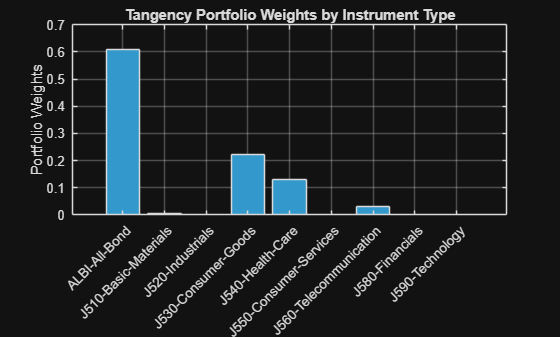


% 12.3.2 Bar plot of portfolio weights
figure;
bar(Wts_train, 'FaceColor',[0.2 0.6 0.8]); % blueish bars
xticks(1:length(tickersWithDesc));
xticklabels(tickersWithDesc);
xtickangle(45); % tilt labels for readability
ylabel('Portfolio Weights');
title('Tangency Portfolio Weights by Instrument Type');
grid on;

### Additional Statistical Sophistication (Test/Training Split)

% 1. Parameters
splits = 0.1:0.05:0.9;  % training fraction
nObs = size(allDataTable,1);

% 2.1 Preallocate results
results = table('Size',[length(splits),10], ...
                'VariableTypes',{'double','double','double','double','double','double','double','double','double','double'}, ...
                'VariableNames',{'TrainFraction','InReturn','InVar','InSharpe','OutBHReturn','OutBHVar','OutBHSharpe','OutCMReturn','OutCMVar','OutCMSharpe'});
% 2.2 Preallocate weight table
tickers = setdiff(allDataTable.Properties.VariableNames,{'STEFI','JIBAR','ALSI','J330','J331'}); % Tickers to Exclude
weightsTable = array2table(NaN(length(splits), length(tickers)), 'VariableNames', tickers);

% 3. Loop over training/test splits
for i = 1:length(splits)
    trainFrac = splits(i);
    splitPoint = floor(trainFrac * nObs);
    
    % 3.1 Split data
    train = allDataTable(1:splitPoint,:);
    test  = allDataTable(splitPoint+1:end,:);
    
    % 3.2 Compute returns
    trainReturnsTable = tick2ret(train,'Method','continuous');
    testReturnsTable = tick2ret(test,'Method','continuous');
    
    % 3.3 Max Sharpe Tangency Portfolio on training set
    [Wts_train,retSR,rskSR,ERFR_Train] = maxSharpeRatio(trainReturnsTable, tickers, 'JIBAR');
    
    % 3.4 Store training weights
    weightsTable{i,:} = Wts_train;
    
    % 3.5 Compute in-sample Sharpe, return, variance
    inRet = 12*retSR;
    inVar = (sqrt(12)*rskSR)^2;
    inSharpe = sharpeRatioM2Y(retSR, rskSR, trainReturnsTable, "JIBAR");
    
    % 3.6 Implement Buy-and-Hold on test set
    [bhMean, bhSd] = buyHold(testReturnsTable,Wts_train,tickers);
    outBHRet = (1 + bhMean)^(12) - 1;
    outBHVar = (sqrt(12)*bhSd)^2;
    outBHSharpe = sharpeRatioM2Y(bhMean, bhSd, testReturnsTable, "JIBAR");

    % 3.6 Implement Buy-and-Hold on test set
    [cmMean, cmSd] = constantMix(testReturnsTable,Wts_train,tickers);
    outCMRet = (1 + cmMean)^(12) - 1;
    outCMVar = (sqrt(12)*cmSd)^2;
    outCMSharpe = sharpeRatioM2Y(cmMean, cmSd, testReturnsTable, "JIBAR");

    % 3.7 Store results
    results.TrainFraction(i) = trainFrac;
    results.InReturn(i) = inRet;
    results.InVar(i) = inVar;
    results.InSharpe(i) = inSharpe;
    results.OutBHReturn(i) = outBHRet;
    results.OutBHVar(i) = outBHVar;
    results.OutBHSharpe(i) = outBHSharpe;
    results.OutCMReturn(i) = outCMRet;
    results.OutCMVar(i) = outCMVar;
    results.OutCMSharpe(i) = outCMSharpe;
end

% 4. Display results table
disp(results);

    TrainFraction    InReturn      InVar      InSharpe    OutBHReturn    OutBHVar     OutBHSharpe    OutCMReturn    OutCMVar     OutCMSharpe
    _____________    ________    _________    ________    ___________    _________    ___________    ___________    _________    ___________

         0.1         0.39911     0.0064747     6.8827        0.18982      0.027114        1.0676        0.18665      0.026964         1.054 
        0.15         0.35611      0.011851     4.3713        0.15371       0.02009       0.99721        0.15263      0.019301        1.0106 
         0.2         0.35258      0.011707     4.0527        0.12278      0.016756       0.8829


% 5. Display weights table
disp(weightsTable);

       ALBI          J510          J520         J530         J540          J550          J560          J580          J590   
    __________    __________    __________    ________    __________    __________    __________    __________    __________

             0       0.11144    2.2204e-16    0.078363       0.81019    2.2204e-16    1.8489e-32    1.8489e-32    4.9304e-32
      0.096193    2.2204e-16    7.3956e-32    0.041331        0.3747    2.4652e-32      0.034513       0.45326    2.2204e-16
       0.15278    2.2204e-16    2.2204e-16    0.056199        0.2147    7.3956e-32      0.057806       0.51851    2.2204e-16
      0.057038      0.099712     2.264e-33     0.17827      0.066598

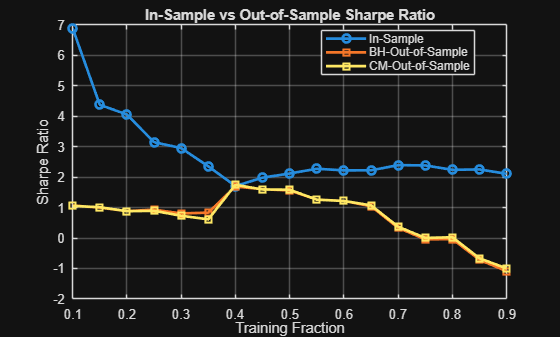


% 6. Plot Sharpe Ratio
figure;
plot(results.TrainFraction, results.InSharpe, '-o', 'LineWidth',2, 'DisplayName','In-Sample');
hold on;
plot(results.TrainFraction, results.OutBHSharpe, '-s', 'LineWidth',2, 'DisplayName','BH-Out-of-Sample');
plot(results.TrainFraction, results.OutCMSharpe, '-s', 'LineWidth',2, 'DisplayName','CM-Out-of-Sample');
xlabel('Training Fraction');
ylabel('Sharpe Ratio');
title('In-Sample vs Out-of-Sample Sharpe Ratio');
legend('Location','best');
grid on;
hold off;

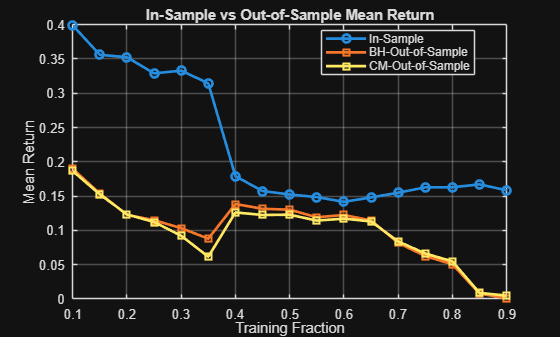

% 7. Plot Mean Return vs Training Fraction
figure;
plot(results.TrainFraction, results.InReturn, '-o', 'LineWidth',2, 'DisplayName','In-Sample');
hold on;
plot(results.TrainFraction, results.OutBHReturn, '-s', 'LineWidth',2, 'DisplayName','BH-Out-of-Sample');
plot(results.TrainFraction, results.OutCMReturn, '-s', 'LineWidth',2, 'DisplayName','CM-Out-of-Sample');
xlabel('Training Fraction');
ylabel('Mean Return');
title('In-Sample vs Out-of-Sample Mean Return');
legend('Location','best');
grid on;
hold off;

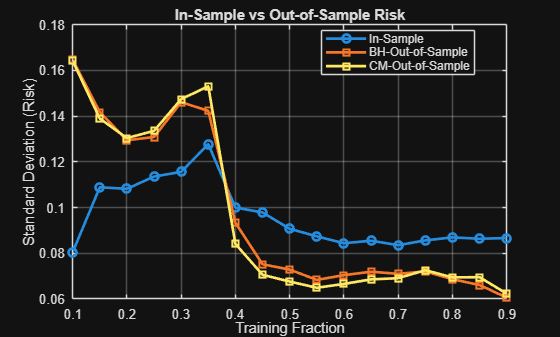


% 8. Plot Standard Deviation vs Training Fraction
figure;
plot(results.TrainFraction, sqrt(results.InVar), '-o', 'LineWidth',2, 'DisplayName','In-Sample');
hold on;
plot(results.TrainFraction, sqrt(results.OutBHVar), '-s', 'LineWidth',2, 'DisplayName','BH-Out-of-Sample');
plot(results.TrainFraction, sqrt(results.OutCMVar), '-s', 'LineWidth',2, 'DisplayName','CM-Out-of-Sample');
xlabel('Training Fraction');
ylabel('Standard Deviation (Risk)');
title('In-Sample vs Out-of-Sample Risk');
legend('Location','best');
grid on;
hold off;

## Experiment 2

% 1. Parameters
windowFrac = 0.3;                                % training fraction of total data
nObs = size(allDataTable,1);                     % total months
windowSize = floor(windowFrac * nObs);           % training window size in months

tickers = setdiff(allDataTable.Properties.VariableNames, ...
    {'STEFI','JIBAR','ALSI','J330','J331'});  % Excluded Tickers

% 2. Preallocate result time series
nSteps = nObs - windowSize;
BHresults = table('Size',[nSteps,7], ...
    'VariableTypes',{'double','double','double','double','double','double','double'}, ...
    'VariableNames',{'BH_InReturn','BH_InVar','BH_InSharpe','BH_OutReturn','BH_OutVar','BH_OutSharpe','BH_SharpeDiff'});
RWresults = table('Size',[nSteps,7], ...
    'VariableTypes',{'double','double','double','double','double','double','double'}, ...
    'VariableNames',{'RW_InReturn','RW_InVar','RW_InSharpe','RW_OutReturn','RW_OutVar','RW_OutSharpe','RW_SharpeDiff'});

% 3. Buy-and-Hold weights (fixed from first window)
train_BH = allDataTable(1:windowSize,:);
trainReturns_BH = tick2ret(train_BH,'Method','continuous');
[Wts_BH,retSR_BH,rskSR_BH,~] = maxSharpeRatio(trainReturns_BH, tickers, 'JIBAR');

% 4. Store in-sample Sharpe for BH (optional, not varying by time)
inSharpeBH = sharpeRatioM2Y(retSR_BH, rskSR_BH, trainReturns_BH, "JIBAR");

% 5. Loop for both RW and BH time-series
for t = 1:nSteps
    % 5.1 Rolling Window Training 
    train_RW = allDataTable(t:(t+windowSize-1),:);
    trainReturns_RW = tick2ret(train_RW,'Method','continuous');
    
    [Wts_RW,retSR_RW,rskSR_RW,~] = maxSharpeRatio(trainReturns_RW, tickers, 'JIBAR');
    inSharpeRW = sharpeRatioM2Y(retSR_RW, rskSR_RW, trainReturns_RW, "JIBAR");
    
    % 5.2 Test month (same for BH and RW) 
    testRow = [train_RW(end,:); allDataTable(t+windowSize,:)];  % one month forward
    testReturns = tick2ret(testRow,'Method','continuous');
    
    % 5.3 Buy-and-Hold fixed weights 
    [bhMean, bhSd] = buyHold(testReturns, Wts_BH, tickers);
    BHresults.BH_InReturn(t) = retSR_BH;
    BHresults.BH_InVar(t) = rskSR_BH^2;
    BHresults.BH_Sharpe(t) = inSharpeBH;
    BHresults.BH_OutReturn(t) = bhMean;
    BHresults.BH_OutVar(t) = bhSd^2;
    BHresults.BH_OutSharpe(t) = sharpeRatioM2Y(bhMean, bhSd, testReturns, "STEFI");
    BHresults.BH_SharpeDiff(t) =abs(sharpeRatioM2Y(bhMean, bhSd, testReturns, "STEFI") -inSharpeBH);

    % 5.4 Rolling Window updated weights 
    [rwMean, rwSd] = buyHold(testReturns, Wts_RW, tickers);
    RWresults.RW_InReturn(t) = retSR_RW;
    RWresults.RW_InVar(t) = rskSR_RW^2;
    RWresults.RW_InSharpe(t) = inSharpeRW;
    RWresults.RW_OutReturn(t) = rwMean;
    RWresults.RW_OutVar(t) = rwSd^2;
    RWresults.RW_OutSharpe(t) = sharpeRatioM2Y(rwMean, rwSd, testReturns, "STEFI");
    RWresults.RW_SharpeDiff(t) = abs(sharpeRatioM2Y(rwMean, rwSd, testReturns, "STEFI") -inSharpeRW); 
end


### Results

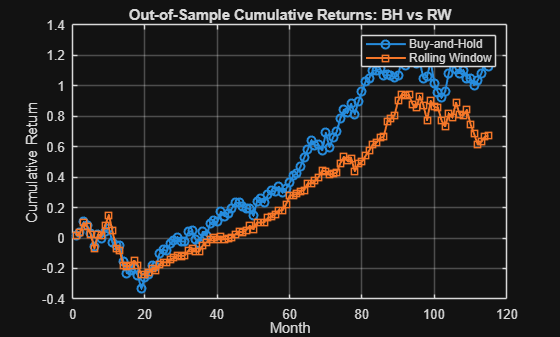


% 6. Time-Series of Strategy Performance (Out-of-Sample)
% 6.1 Compute cumulative returns
cumBH = cumprod(1 + BHresults.BH_OutReturn) - 1;
cumRW = cumprod(1 + RWresults.RW_OutReturn) - 1;
% 6.2 Plot
figure;
plot(1:nSteps, cumBH, '-o', 'LineWidth',1.5);
hold on;
plot(1:nSteps, cumRW, '-s', 'LineWidth',1.5);
xlabel('Month');
ylabel('Cumulative Return');
title('Out-of-Sample Cumulative Returns: BH vs RW');
legend('Buy-and-Hold','Rolling Window');
grid on;
hold off;

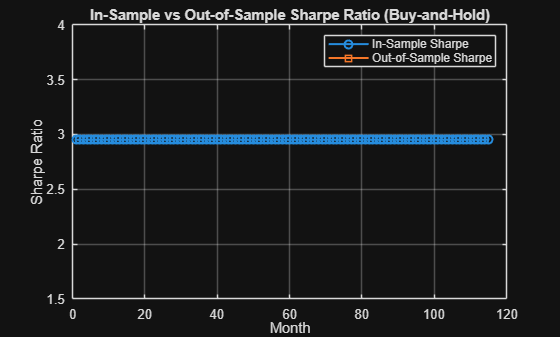


% 7. Compare In-Sample Sharpe Ratios vs Out-of-Sample BH Sharpe
figure;
plot(1:nSteps, BHresults.BH_Sharpe, '-o','LineWidth',1.5);
hold on;
plot(1:nSteps, BHresults.BH_OutSharpe, '-s','LineWidth',1.5);
xlabel('Month');
ylabel('Sharpe Ratio');
title('In-Sample vs Out-of-Sample Sharpe Ratio (Buy-and-Hold)');
legend('In-Sample Sharpe','Out-of-Sample Sharpe');
grid on;
hold off;

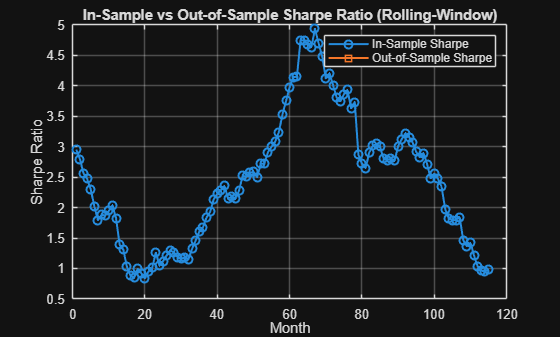


% 8. Compare In-Sample vs Out-of-Sample Sharpe for Rolling-Window
figure;
plot(1:nSteps, RWresults.RW_InSharpe, '-o', 'LineWidth', 1.5);
hold on;
plot(1:nSteps, RWresults.RW_OutSharpe, '-s', 'LineWidth', 1.5);
xlabel('Month');
ylabel('Sharpe Ratio');
title('In-Sample vs Out-of-Sample Sharpe Ratio (Rolling-Window)');
legend('In-Sample Sharpe', 'Out-of-Sample Sharpe');
grid on;
hold off;


% 9.  Table of Portfolio Statistics (two columns: BH and RW)
stats = {'MeanReturn'; 'Variance'; 'Sharpe'; 'MinReturn'; 'MaxReturn'; 'MinSharpe'; 'MaxSharpe'};
% 9.1 BH statistics vector
BHstats = [ ...
    mean(BHresults.BH_OutReturn); ...
    mean(BHresults.BH_OutVar); ...
    mean(BHresults.BH_OutSharpe); ...
    min(BHresults.BH_OutReturn); ...
    max(BHresults.BH_OutReturn); ...
    min(BHresults.BH_OutSharpe); ...
    max(BHresults.BH_OutSharpe) ...
];
% 9.2 RW statistics vector
RWstats = [ ...
    mean(RWresults.RW_OutReturn); ...
    mean(RWresults.RW_OutVar); ...
    mean(RWresults.RW_OutSharpe); ...
    min(RWresults.RW_OutReturn); ...
    max(RWresults.RW_OutReturn); ...
    min(RWresults.RW_OutSharpe); ...
    max(RWresults.RW_OutSharpe) ...
];

% 9.3 Combine into a table
SummaryTable = table(BHstats, RWstats, 'RowNames', stats, 'VariableNames', {'BuyHold','RollingWindow'});
% 9.4 Display
disp(SummaryTable);

                   BuyHold     RollingWindow
                  _________    _____________

    MeanReturn    0.0074689      0.0050991  
    Variance              0              0  
    Sharpe              NaN            NaN  
    MinReturn      -0.11337        -0.1091  
    MaxReturn        0.1094       0.099015  
    MinSharpe          -Inf           -Inf  
    MaxSharpe           Inf            Inf  



## Additional Statistial Sophistication

% 1. Testing Window Fractions
windowFracs = 0.1:0.05:0.9;
nFracs = length(windowFracs);

% 2. Preallocate summary table
SummaryWindow = table('Size',[nFracs, 7], ...
    'VariableTypes', repmat("double",1,7), ...
    'VariableNames', {'WindowFrac', 'BH_MeanReturn','BH_Std','BH_Sharpe','RW_MeanReturn','RW_Std','RW_Sharpe'});

% 3. Loop
for w = 1:nFracs
    windowFrac = windowFracs(w);
    nObs = size(allDataTable,1);
    windowSize = floor(windowFrac * nObs);
    nSteps = nObs - windowSize;
    
    % 3.1 preallocate tables
    BHresults = table('Size',[nSteps,7], 'VariableTypes', repmat("double",1,7), ...
        'VariableNames',{'BH_InReturn','BH_InVar','BH_InSharpe','BH_OutReturn','BH_OutVar','BH_OutSharpe','BH_SharpeDiff'});
    RWresults = table('Size',[nSteps,7], 'VariableTypes', repmat("double",1,7), ...
        'VariableNames',{'RW_InReturn','RW_InVar','RW_InSharpe','RW_OutReturn','RW_OutVar','RW_OutSharpe','RW_SharpeDiff'});
    
    % 3.2 Buy-and-Hold fixed weights 
    train_BH = allDataTable(1:windowSize,:);
    trainReturns_BH = tick2ret(train_BH,'Method','Simple');
    [Wts_BH,retSR_BH,rskSR_BH,~] = maxSharpeRatio(trainReturns_BH, tickers, 'STEFI');
    inSharpeBH = sharpeRatioM2Y(retSR_BH, rskSR_BH, trainReturns_BH, "STEFI");

    % 3.3 Loop over nSteps to fill BHresults and RWresults 
    for t = 1:nSteps
        % 3.3.1 Rolling Window Training 
        train_RW = allDataTable(t:(t+windowSize-1),:);
        trainReturns_RW = tick2ret(train_RW,'Method','Simple');
        [Wts_RW,retSR_RW,rskSR_RW,~] = maxSharpeRatio(trainReturns_RW, tickers, 'STEFI');
        inSharpeRW = sharpeRatioM2Y(retSR_RW, rskSR_RW, trainReturns_RW, "STEFI");
    
        % 3.3.2 Test month (same for BH and RW) 
        testRow = [train_RW(end,:); allDataTable(t+windowSize,:)]; 
        testReturns = tick2ret(testRow,'Method','Simple');
    
        % 3.3.3 Buy-and-Hold fixed weights
        [bhMean,bhSd] = buyHold(testReturns,Wts_BH,tickers);
        BHresults.BH_OutReturn(t) = bhMean;
        BHresults.BH_OutVar(t) = bhSd^2;
        BHresults.BH_OutSharpe(t) = sharpeRatioM2Y(bhMean,bhSd,testReturns,"STEFI");

        % 3.3.4 Rolling Window updated weights 
        [rwMean,rwSd] = buyHold(testReturns,Wts_RW,tickers);
        RWresults.RW_OutReturn(t) = rwMean;
        RWresults.RW_OutVar(t) = rwSd^2;
        RWresults.RW_OutSharpe(t) = sharpeRatioM2Y(rwMean,rwSd,testReturns,"STEFI");
    end

    % 3.3.5 Store summary metrics in the windowFrac table 
    SummaryWindow.WindowFrac(w)    = windowFrac;
    SummaryWindow.BH_MeanReturn(w) = mean(BHresults.BH_OutReturn);
    SummaryWindow.BH_Std(w)        = sqrt(mean(BHresults.BH_OutVar));
    SummaryWindow.BH_Sharpe(w)     = mean(BHresults.BH_OutSharpe);
    SummaryWindow.RW_MeanReturn(w) = mean(RWresults.RW_OutReturn);
    SummaryWindow.RW_Std(w)        = sqrt(mean(RWresults.RW_OutVar));
    SummaryWindow.RW_Sharpe(w)     = mean(RWresults.RW_OutSharpe);
end

% 4. Display results
disp(SummaryWindow);

    WindowFrac    BH_MeanReturn    BH_Std    BH_Sharpe    RW_MeanReturn    RW_Std    RW_Sharpe
    __________    _____________    ______    _________    _____________    ______    _________

        0.1          0.016326        0          NaN          0.011565        0          NaN   
       0.15          0.013975        0          NaN          0.014086        0          NaN   
        0.2           0.01148        0          NaN           0.01034        0          NaN   
       0.25          0.011214        0          NaN         0.0083398        0          NaN   
        0.3         0.0092498        0          NaN          0.010979        0          NaN   
       0.35          0.007052        0          NaN          0.010799        0          NaN   
 

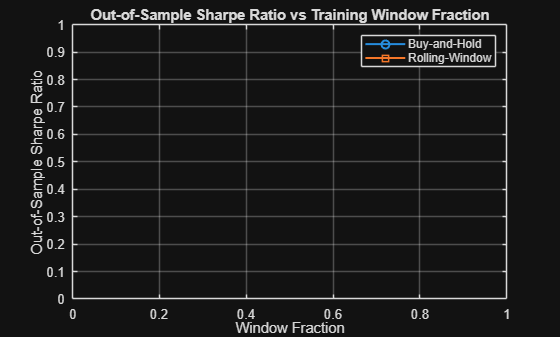


% 5. Plot Sharpe Ratio vs Window Fraction
figure;
plot(SummaryWindow.WindowFrac, SummaryWindow.BH_Sharpe, '-o', 'LineWidth', 1.5);
hold on;
plot(SummaryWindow.WindowFrac, SummaryWindow.RW_Sharpe, '-s', 'LineWidth', 1.5);
xlabel('Window Fraction');
ylabel('Out-of-Sample Sharpe Ratio');
title('Out-of-Sample Sharpe Ratio vs Training Window Fraction');
legend('Buy-and-Hold', 'Rolling-Window');
grid on;
hold off;